# Práctica 8 - Cámaras

## Ejercicio 1

R1 = rotateZ(90) * rotateY(90)

R1 =     0.0000   -1.0000    0.0000
    0.0000    0.0000    1.0000
   -1.0000         0    0.0000


R2 = rotateZ(90) * rotateX(90)

R2 =     0.0000   -0.0000    1.0000
    1.0000    0.0000   -0.0000
         0    1.0000    0.0000


R3 = rotateZ(30) * rotateY(90) * rotateX(45)

R3 =     0.0000    0.2588    0.9659
    0.0000    0.9659   -0.2588
   -1.0000    0.0000    0.0000


Notar que aplicamos las rotaciones en el orden especificado (ZYX). Cuando no es necesario rotar en algún eje, se multiplica por la matriz identidad.

## Ejercicio 2

X = [3 4 -3]

X =      3     4    -3


C = [5 3 5]

C =      5     3     5


R = rotateY(90)

R =     0.0000         0    1.0000
         0    1.0000         0
   -1.0000         0    0.0000


X_cam = R * (X-C)'

X_cam =    -8.0000
    1.0000
    2.0000


## Ejercicio 3

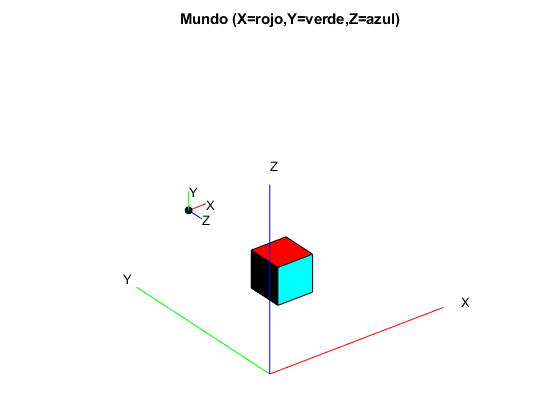

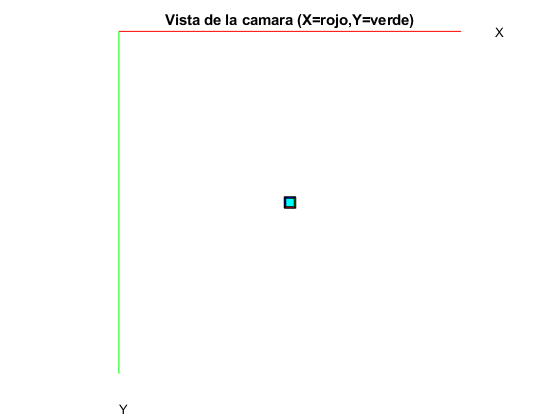

f = 0.1;
s = 0;
px = 0.5; py = 0.5;
theta_x = pi/2; %-3*pi/4;
theta_y = 0;
theta_z = 0; %pi/4;%0;
C = [3 10 3]'; % enfrentado

generar_camara(f, s, px, py, theta_x, theta_y, theta_z, C)

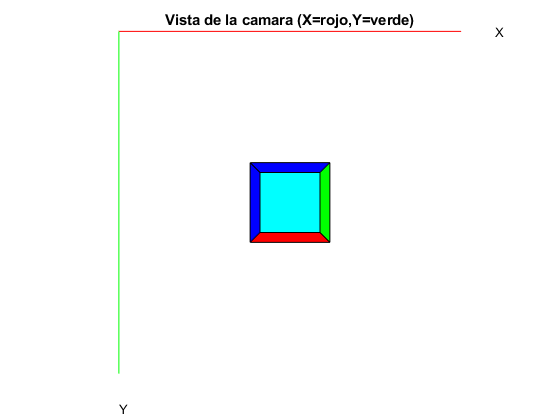

f = 0.7;
s = 0;
px = 0.5; py = 0.5;
theta_x = pi/2; %-3*pi/4;
theta_y = 0;
theta_z = 0; %pi/4;%0;
C = [3 10 3]'; % enfrentado

generar_camara(f, s, px, py, theta_x, theta_y, theta_z, C)

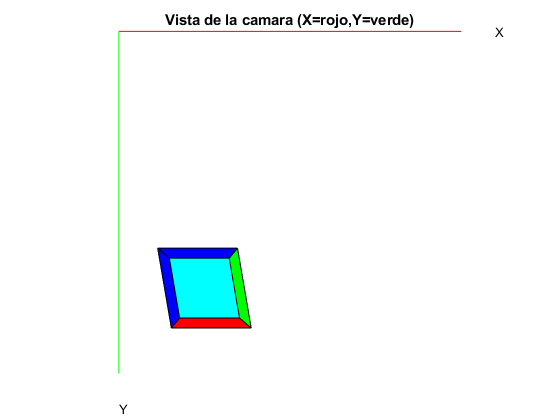

f = 0.7;
s = 0.12;
px = 0.25; py = 0.75;
theta_x = pi/2; %-3*pi/4;
theta_y = 0;
theta_z = 0; %pi/4;%0;
C = [3 10 3]'; % enfrentado

generar_camara(f, s, px, py, theta_x, theta_y, theta_z, C)

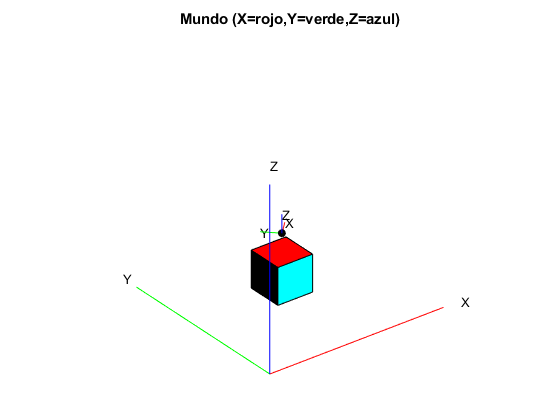

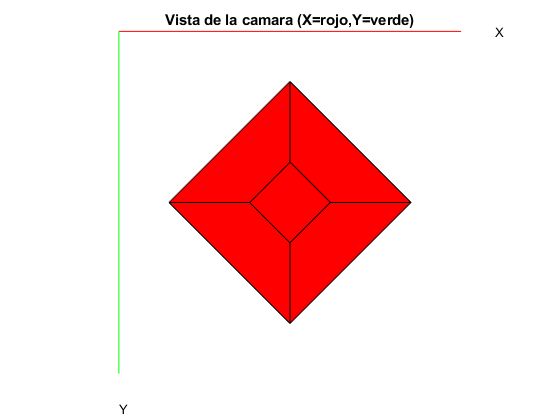

f = 0.25;
s = 0;
px = 0.5; py = 0.5;
theta_x = 0;
theta_y = 0;
theta_z = pi/4;
C = [3 3 5]';  % desde arriba, centrado en el cubo

generar_camara(f, s, px, py, theta_x, theta_y, theta_z, C)

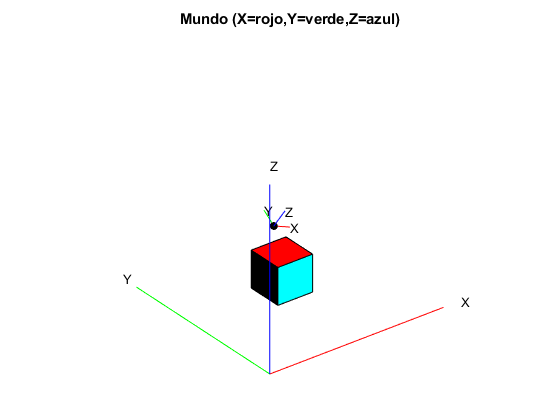

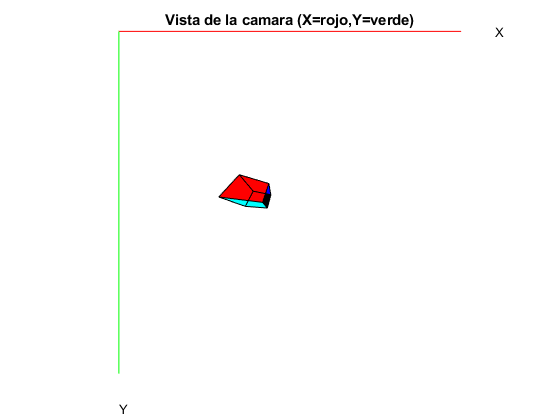

f = 0.1;
s = 0;
px = 0.5; py = 0.5;
theta_x = pi/8;
theta_y = pi/8;
theta_z = 0;
C = [1 1 7]';

generar_camara(f, s, px, py, theta_x, theta_y, theta_z, C)

## Ejercicio 4

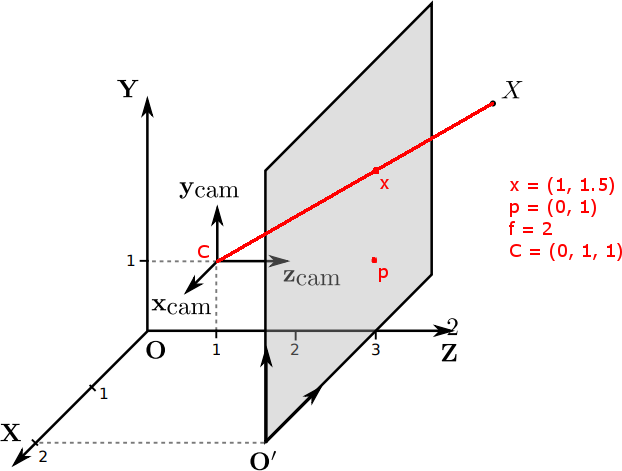

X = [2 3 4]';
x_cam = 0;
y_cam = 1;
z_cam = 1;

$z_{cam} = 1$ y el plano de la imagen parece estar ubicado en $Z=3$, entonces:

f = 3 - z_cam

f = 2

$x = (\frac{fX}{fZ}, \frac{fY}{fZ})$, luego:

x = [f*X(1) / f*X(3); f*X(2) / f*X(3)]

x =      8
    12


C = [x_cam y_cam z_cam]'

C =      0
     1
     1


Definimos ahora la matriz de calibración $K$

px = 0;
py = 1;
s = 0;  % Suponemos que no hay skewness

K = [f 0 px
     0 f py
     0 0  1]

K =      2     0     0
     0     2     1
     0     0     1


% Asumimos también que la cámara no está rotada
R = eye(3);
Ri = inv(R);

P = K*Ri*[eye(3) - C]

P =      2     0     0
    -3    -1    -2
    -1    -1     0


x = P*X

x =      4
   -17
    -5


xin = [x(1,:)./x(3,:);x(2,:)./x(3,:)]  % x en coordenadas inhomogeneas

xin =    -0.8000
    3.4000
